## Matlab Error anaylsis

Error Anaylsis of follwing equation


$$\frac{1}{x}\ln\left(\frac{((1-R)^4+4T^2R^2)^{0.5} - (1-R)^2}{2T^2R^2}\right)$$


where b is the section within the ln

where 

load ErrorAnalysis.mat R_1
load ErrorAnalysis.mat T
load ErrorAnalysis.mat alpha_1
load ErrorAnalysis.mat energy_ev

R = R_1

R =     0.7665
    0.7672
    0.7680
    0.7687
    0.7695
    0.7703
    0.7711
    0.7718
    0.7726
    0.7734


x = R

x =     0.7665
    0.7672
    0.7680
    0.7687
    0.7695
    0.7703
    0.7711
    0.7718
    0.7726
    0.7734


y = T

y =     3.2449
    4.4550
    6.8499
   11.2423
    6.1956
    4.0276
    3.0084
    2.4020
    2.3710
    2.2112


z = 0.000625 %0.000417

z = 6.2500e-04


$$\frac{d}{dx}=\frac{x^2y^2\left(\frac{ \frac{8xy^2-4(1-x)^3}{2 \sqrt{4x^2y^2+(1-x)^4} }+2(1-x) }{2x^2y^2} -  \frac{ \sqrt{4x^2y^2+(1-x)^4}-(1-x)^2 }{x^3y^2}\right)}{z(\sqrt{4x^2y^2+(1+x)^4}-(1-x)^2)}$$
 

which in plain text is

dx = (2.*x.^2.*y.^2.*(((8.*x.*y.^2-4.*(1-x).^3)./(2.*sqrt(4.*x.^2.*y.^2+(1-x).^4)) +2.*(1-x))./(2.*x.^2.*y.^2) - (sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)./(x.^3.*y.^2)))./(z.*sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)

dx =   114.5313
  166.4852
  277.2220
  512.8416
  250.0561
  152.6506
  109.6601
   84.8551
   84.2004
   78.0922



$$\frac{d}{dy} = \frac{2x^2y^2\left(\frac{2}{y\sqrt{4x^2y^2+(1-x)^4}} - \frac{\sqrt{4x^2y^2+(1-x)^4}-(1-x)^2}{x^2y^3}\right)}{z(\sqrt{4x^2y^2+(1+x)^4}-(1-x)^2)}$$


dy = (2.*x.^2.*y.^2.*(((2)./(y.*sqrt(4.*x.^2.*y.^2+(1-x).^4)) - (sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)./(x.^2.*y.^3)))./(z.*sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2))

dy =    29.1777
   30.2661
   32.1768
   35.8070
   32.2645
   30.9765
   30.4502
   30.1729
   30.3932
   30.4833



$$\frac{d}{dx} = \frac{1}{z^2}\ln\left(\frac{((1-R)^4+4T^2R^2)^{0.5} - (1-R)^2}{2T^2R^2}\right)$$


dz = ((1)./(z.^2)).*log((sqrt((1-R).^4+4.*T.^2.*R.^2)-(1-R).^2)./(2.*T.^2.*R.^2))

dz = 	1.0e+06 *

   -2.3607
   -3.1667
   -4.2634
   -5.5291
   -4.0125
   -2.9201
   -2.1830
   -1.6163
   -1.5858
   -1.4120


Errors of respective variables

% error on voltage
errVoltage = 0.001*ones(size(voltages_1));
% error on Transmission Coefficient
%errT = 0.2*ones(size(V0_1))
errT = T.*(((errVoltage./voltages_0).^2+(errVoltage./voltages_1).^2).^0.5);
% error on R
errR = 0.01;
errz = 0.0001

errz = 1.0000e-04

errx = errR*ones(size(voltages_1));
erry = errT;

err_alpha = sqrt((dx.*errx).^(2)+(dy.*erry).^(2)+(dz.*errz).^(2)+(dz.*errz).^(2));
% err_R_alpha = real(err_alpha);

alpha_GaAs = alpha_1

alpha_GaAs = 	1.0e+03 *

    0.0119
    0.0069
    0.0025
         0
    0.0083
    0.0177
    0.0269
    0.0359
    0.0384
    0.0429


eV_energy = energy_ev

eV_energy =     3.5472
    3.5371
    3.5271
    3.5171
    3.5071
    3.4973
    3.4874
    3.4777
    3.4680
    3.4583



err_B = err_alpha./alpha_GaAs

err_B = 	1.0e+05 *

    0.4456
    2.5530
    9.1987
       Inf
    7.6175
       Inf
    0.1174
    0.0755
    0.0770
    0.0807


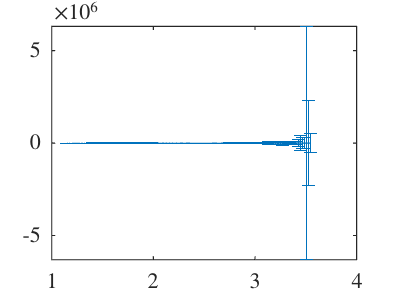


errorbar(eV_energy(1:2:end),alpha_GaAs(1:2:end),err_alpha(1:2:end),err_alpha(1:2:end))

 
% errorbar(wavelength,T,errT,errT)
 
% 5help_T = errT./T

help_alpha = (err_B./alpha_GaAs).*100

help_alpha = 	1.0e+07 *

    0.0374
    0.3705
    3.6807
       Inf
    0.9193
       Inf
    0.0044
    0.0021
    0.0020
    0.0019
